syms A
syms B
syms C
syms x
syms y
syms z

syms P
syms Q
syms R

Имеем поле $F\left(P\left(x,y\right),Q\left(x,y\right)\right)$, где


P=3*x^3+A*x^2*y+B*x*y^2+C*y^3

$$P = 3\,x^{3}+A\,x^{2}\,y+B\,x\,y^{2}+C\,y^{3}$$

Q=2*x^3+4*x^2*y+9*x*y^2+4*y^3

$$Q = 2\,x^{3}+4\,x^{2}\,y+9\,x\,y^{2}+4\,y^{3}$$

%P = 8*x^3+A*x^2*y+B*x*y^2+C*y^3
%Q = (8/3)*x^3+5*x^2*y+27*x*y^2+4*y^3
%P=5*x*y+8*y
%Q=4*x^2+12*y^2
R = sym(0);
F=[P,Q,R]

$$F = \left(\begin{array}{ccc} 3\,x^{3}+A\,x^{2}\,y+B\,x\,y^{2}+C\,y^{3} & 2\,x^{3}+4\,x^{2}\,y+9\,x\,y^{2}+4\,y^{3} & 0 \end{array}\right)$$

Из выражения $\mathrm{rot}\left(F\right)=0$ или $\frac{\partial Q}{\partial x}=\frac{\partial P}{\partial у}$ найдем коэффициенты $A,B,C$

rot = curl(F,[x,y,z]);
rot = rot(3)

$$rot = 8\,x\,y-A\,x^{2}-3\,C\,y^{2}+6\,x^{2}+9\,y^{2}-2\,B\,x\,y$$

symvar(rot);
vrs=[x,y];
coefs = coeffs(rot,vrs);
vec=sym([0,0,0]);
coefs==vec

$$ans = \left(\begin{array}{ccc} 9-3\,C=0 & 8-2\,B=0 & 6-A=0 \end{array}\right)$$

slv = solve(coefs==vec);
A=sym(slv.A)

$$A = 6$$

B=sym(slv.B)

$$B = 4$$

C=sym(slv.C)

$$C = 3$$

v=symvar(P);
P = subs(P,v(1),A);
P = subs(P,v(2),B);
P = subs(P,v(3),C);
P = simplify(P)

$$P = 3\,x^{3}+6\,x^{2}\,y+4\,x\,y^{2}+3\,y^{3}$$

syms x1
syms y1
iP = subs(P,x,x1);

$$iP = 3\,{x_{1}}^{3}+6\,{x_{1}}^{2}\,y+4\,x_{1}\,y^{2}+3\,y^{3}$$

iP = subs(iP,y,sym(0));

$$iP = 3\,{x_{1}}^{3}$$

iQ = subs(Q,y,y1);

$$iQ = 2\,x^{3}+4\,x^{2}\,y_{1}+9\,x\,{y_{1}}^{2}+4\,{y_{1}}^{3}$$

syms x1
syms y1


Восстановим потенциал


$$U\left(x,y\right)=U\left(0,0\right)+\int_0^x P\left(t,0\right)\mathrm{dt}+\int_0^y Q\left(x,t\right)\mathrm{dt}$$


Примем $U\left(0,0\right)=0$

U = int(iP,x1,0,x) + int(iQ,y1,0,y)

$$U = \frac{3\,x^{4}}{4}+2\,x^{3}\,y+2\,x^{2}\,y^{2}+3\,x\,y^{3}+y^{4}$$

diff(U,x);
P;
diff(U,y);
Q;

Уравнение $U\left(x,y\right)=U\left(1,1\right)$определяет неявную функцию $1=f\left(1\right)$

f = U - subs(subs(U,x,1),y,1)%U(1,1)

$$f = \frac{3\,x^{4}}{4}+2\,x^{3}\,y+2\,x^{2}\,y^{2}+3\,x\,y^{3}+y^{4}-\frac{35}{4}$$

Положим

x1 = 1

x1 = 1

y1 = 1

y1 = 1

**сюда:**

Проведем касательнуй в точке (*x1*,*y1*)

Найдем производную *ff1* в точке *x1*

Найдем аналитическое представление касательной *ty*

Пололжим новый x1 = x1 + eps, где

eps = .1

eps = 0.1000

Если x1 < gz

gz = 1.5

gz = 1.5000

goto **туда^**

gz = ((gz-1) / eps);

pts  =[];

for i=1:gz
    x1=double(x1)
    y1=double(y1)
    %x1
    pts=[pts;[x1,y1]];
    %tangent angle in point x1
    ff1 = -subs(subs(P,x,x1),y,y1)/subs(subs(Q,x,x1),y,y1) %  f'(1)
    %tangent in point x1
    ty = solve((y-y1)==(ff1*(x-x1)),y)
    x1=x1+eps;
    y1 = subs(ty,x,x1);
    'x1'
    double(x1)
    'y1'
    double(y1)
    "--------------------------------------------------------------------------"
end

x1 = 1

y1 = 1

$$ff1 = -\frac{16}{19}$$

$$ty = \frac{35}{19}-\frac{16\,x}{19}$$

ans = 'x1'

ans = 1.1000

ans = 'y1'

ans = 0.9158

ans = "--------------------------------------------------------------------------"

x1 = 1.1000

y1 = 0.9158

$$ff1 = -\frac{114105759}{126681886}$$

$$ty = \frac{9178150359}{4813911668}-\frac{114105759\,x}{126681886}$$

ans = 'x1'

ans = 1.2000

ans = 'y1'

ans = 0.8257

ans = "--------------------------------------------------------------------------"

x1 = 1.2000

y1 = 0.8257

$$ff1 = -\frac{3082821879729173999726590609996814809423928680587}{3180546519732551518255799491471653777693804145508}$$

$$ty = \frac{8902514428561619062237538263193680525445767521922176013180303777}{4476221287844389662734354277401946975839762221231664433190666240}-\frac{3082821879729173999726590609996814809423928680587\,x}{3180546519732551518255799491471653777693804145508}$$

ans = 'x1'

ans = 1.3000

ans = 'y1'

ans = 0.7288

ans = "--------------------------------------------------------------------------"

x1 = 1.3000

y1 = 0.7288

$$ff1 = -\frac{399274218764283991791700546038458560425378089451}{380968594028608821929098413714204298807471552484}$$

$$ty = \frac{560629437349972582346264768836077723260899565458215212629288737}{268082815329235071559690701646722720406028635073597859965173760}-\frac{399274218764283991791700546038458560425378089451\,x}{380968594028608821929098413714204298807471552484}$$

ans = 'x1'

ans = 1.4000

ans = 'y1'

ans = 0.6240

ans = "--------------------------------------------------------------------------"

x1 = 1.4000

y1 = 0.6240

$$ff1 = -\frac{1687971300130865591478541654855146786290379139182237}{1485044446644683930921288952941092852712198798218108}$$

$$ty = \frac{37039903773553765325063680060401384196618613731640881925466581614977}{16720114041344057450335198781238350490889718958908445648475830353920}-\frac{1687971300130865591478541654855146786290379139182237\,x}{1485044446644683930921288952941092852712198798218108}$$

ans = 'x1'

ans = 1.5000

ans = 'y1'

ans = 0.5103

ans = "--------------------------------------------------------------------------"

Получаем массив точек (x,y):

double(pts)

ans =     1.0000    1.0000
    1.1000    0.9158
    1.2000    0.8257
    1.3000    0.7288
    1.4000    0.6240


pts;
mx=double(min(pts(:,1)));
my=double(min(pts(:,2)));
Mx=double(max(pts(:,1)));
My=double(max(pts(:,2)));

Представим на графике точке и аналитическую функцию $f\left(x\right)$:

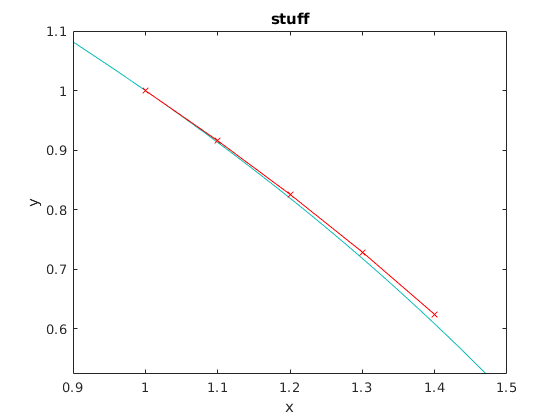

ezplot(f,[mx-eps,Mx+eps,my-eps,My+eps])
hold on
title('stuff')
plot(pts(:,1)',pts(:,2)','-xr')
hold off



%f(1)=1; U(x,y)=U(1,1)
